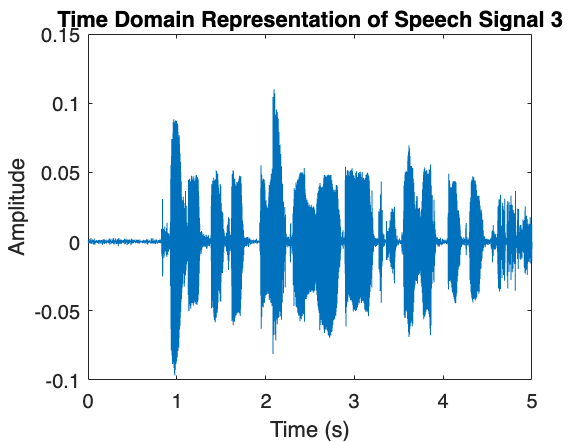

% ECE 2312 Project 1
% Karyn Carrion

% This file plots and saves the recorded speech signal as well
% as the spectrogram 

% Load wav file
filename = '3.wav';
[y, Fs] = audioread(filename);

% Make duration vector to represent elapsed time
t = (0:size(y, 1) - 1) / Fs;

% Plot time domain representation of speech signal
figure;
plot(t, y);
title('Time Domain Representation of Speech Signal 3');
xlabel('Time (s)');
ylabel('Amplitude');

% Save the speech signal
saveas(gcf, 'speech_signal3.png');

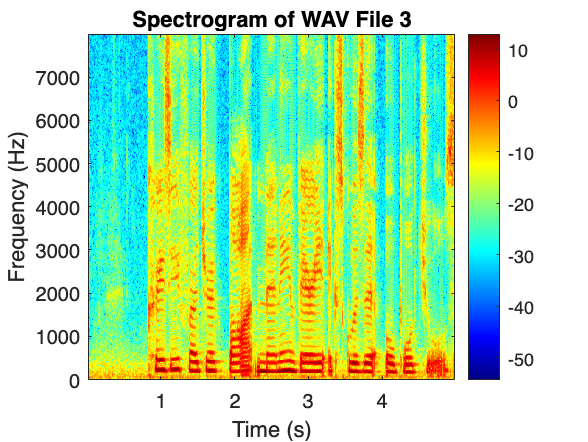


% Set values to generate plot
windowLength = round(0.03 * Fs);
overlap = round(0.02 * Fs);
nfft = 2^nextpow2(windowLength);
frequency = 8000;

% Compute spectrogram
[s, f, t] = spectrogram(y, windowLength, overlap, nfft, Fs, 'yaxis');

% Limit frequency range to 8000 Hz
fIndex = find(f <= frequency, 1, 'last');
s = s(1:fIndex, :);
f = f(1:fIndex);

% Plot the spectrogram
figure;
imagesc(t, f, 10*log10(abs(s)));
axis xy;
colormap('jet');
colorbar;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of WAV File 3');

% Save the spectrogram
saveas(gcf, 'spectrogram3.png');